# Exercise 6.2 - Input-output difference equation

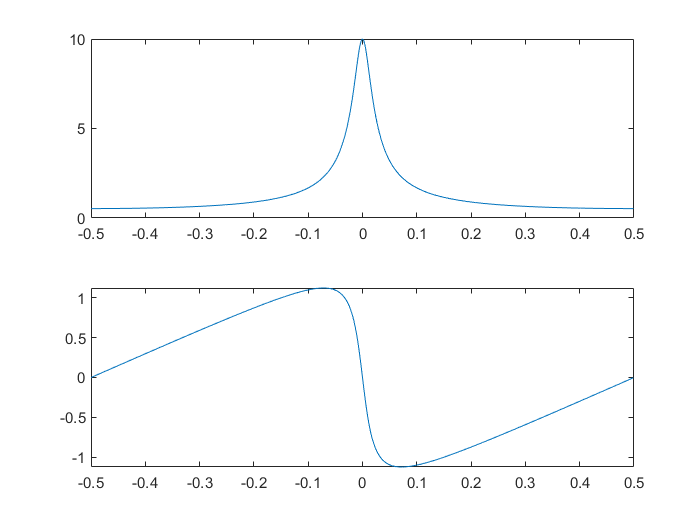

% NOTE: An input-output difference equation may also be refered to
% as a linear constant-coefficient difference equation.

% Input coeficient.
b = 1;

% Output coeficients.
a = [1 -0.9];

% Compute the frequency response of the system (H(f)).
N = 1024;
[H, w] = freqz(b, a, N, 'whole');

% Shift spectrum to the origin.
f = w / (2 * pi) - 0.5;
H = fftshift(H);

% Plot the amplitude and phase of H(f).
subplot(211), plot(f, abs(H));
subplot(212), plot(f, angle(H));

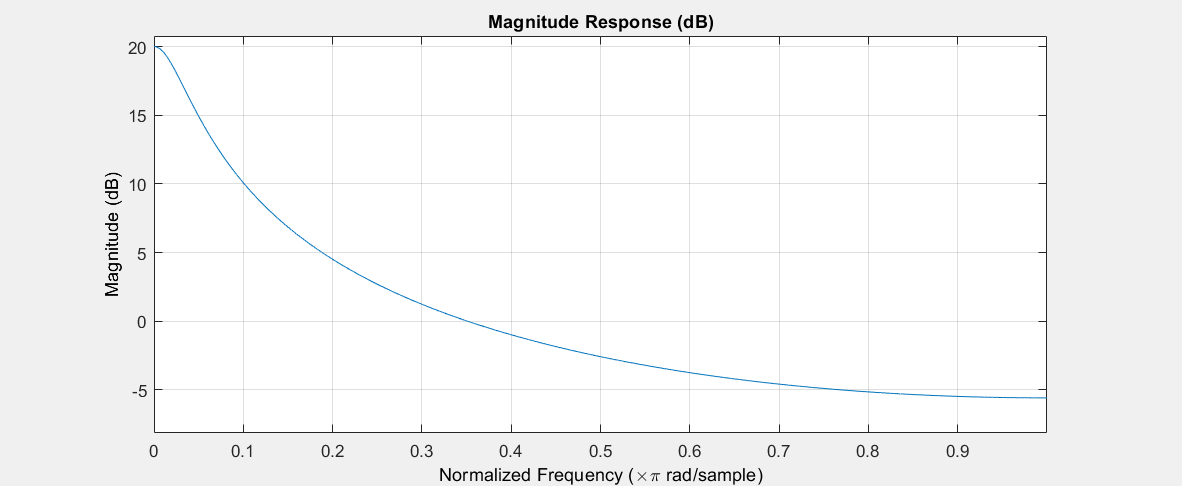

fvtool(b, a); % Alternative for the amplitude.